# Zadanie 2.2

# Najpierw rozwiązujemy zadanie 2.1 

## Zagadnienia cieplno-przepływowe reaktorów jądrowych, Cwiczenia 2, 20-12-2024, Rewizja 2

clear; close all; clc;

## Dane - część danych z zadania 1.1

q_th = 4600e6		% [W] moc cieplna rdzenia

q_th = 4.6000e+09

W = 75643000/3600 	% [kg/s] przepływ chlodziwa przez rdzen

W = 2.1012e+04

p = 155		        % [bar]	ciśnienie	

p = 155

Tin = 295.6		    % [degC] temperatura wlotowa		  			

Tin = 295.6000


N_FA = 241          % ilość kaset paliwowych, FA - Fuel Assemblies [-]

N_FA = 241

N_rod = 265         % ilość prętów w kasecie [-]

N_rod = 265

H = 4200/1000       % wysokość aktywnej częsci rdzenia (kaset paliwowych/prętów paliwowych) [m]

H = 4.2000

skok = 214/1000     % skok siatki kaset paliwowych - odległość między środkami kaset [m]

skok = 0.2140


d_ex = 5/100;       % [m] Długość ekstrapolacji
Pxy = 1.438;        % [-] ????????? Wsp. promieniowy nierównomierności rozkładu - odczytany z mapy rdzenia

## 1) Średni przyrost temperatury w całym rdzeniu i średnim kanale

cp = 1000*XSteam('Cp_pT', p,Tin) % [kJ/kg/K] cieplo wlasciwe dla T wlotowej

cp = 5.3566e+03

deltaT = q_th / (cp*W) 

deltaT = 40.8694

Tout = Tin + deltaT

Tout = 336.4694

Tavg = (Tin+Tout)/2

Tavg = 316.0347


% w średnim kanale będzie identyczny przyrost

## Dodatkowy materiał - demonstracja procesu iteracyjnego

można iteracyjnie poprawić wynik dla 1 iteracji iteracja 1

% iteracja 1
disp('Iteracja 1')

Iteracja 1


cp1 = 1000*XSteam('Cp_pT', p,Tavg) % [kJ/kg/K] cieplo wlasciwe dla T wlotowej

cp1 = 5.9672e+03

deltaT1 = q_th / (cp1*W) 

deltaT1 = 36.6877

Tout1 = Tin + deltaT1

Tout1 = 332.2877


% iteracja 2
disp('Iteracja 2')

Iteracja 2


Tavg2 = (Tin + Tout1)/2

Tavg2 = 313.9438

cp2 = 1000*XSteam('Cp_pT', p,Tavg2) % [kJ/kg/K] cieplo wlasciwe dla T wlotowej

cp2 = 5.8842e+03

deltaT2 = q_th / (cp2*W) 

deltaT2 = 37.2051

Tout2 = Tin + deltaT2

Tout2 = 332.8051

## 2) Przyrost temperatury w rdzeniu w najgorętszym kanale

Przyrost temperatury w rdzeniu w najgorętszym kanale zakładając średni przepływ 

deltaT_max = deltaT*Pxy             % [K] przyrost temperatury

deltaT_max = 58.7702

Tout_max = Tin + deltaT_max         % [K] temperatura na wylocie

Tout_max = 354.3702

Tavg_max = (Tin + Tout_max)/2       % [K] srednia temperatura

Tavg_max = 324.9851


disp('Iteracja 1')

Iteracja 1


cp_max1 = 1000*XSteam('Cp_pT', p,Tavg_max) % [kJ/kg/K] cieplo wlasciwe dla T wlotowej

cp_max1 = 6.4136e+03

deltaT1_max = Pxy*q_th / (cp_max1*W) 

deltaT1_max = 49.0848

% q_th/W  jest takie samo dla kanału jak i dla całego rdzenia - w tym
% przypadku i przy tych założeniach
Tout_max1 = Tin + deltaT1_max

Tout_max1 = 344.6848

% mozna wiecej ale dla prostoty jedna iteracja

## 3) Dla kanału średniego i najgorętszego oblicz i wykreśl rozkład temperatury/entalpi wzdłuż kanału oraz rozkład mocy liniowej

He = H + 2*d_ex                 % [m] wysokość rdzenia z dodanymi 2x długościami ekstrpolacji

He = 4.3000

W_kanal = W / (N_FA*N_rod)		% [kg/s] przepływ przez pojedyńczy kanał

W_kanal = 0.3290

q_kanal = q_th / (N_FA*N_rod)   % [W] moc sredniego kanalu - srednia moc kanalu

q_kanal = 7.2027e+04

q_prim_kanal = q_kanal / H		% [W/m] srednia moc liniowa

q_prim_kanal = 1.7149e+04

Wyliczenia liniowej mocy  maksylamej dla rozkladu kosinusoidalnego.

Osiowy rozkład mocy jest typu ścięty kosinus. Długość ekstrapolacji załóż 5 cm.

Maksymalną moc liniowa zadana równaniem - teoretyczna wartość dla rozkładu ścięty kosinus

q0_prim = pi*q_kanal/(He*2*sin((pi*H)/(2*He)))      % [W/m] maksymalna moc dla średniego kanału

q0_prim = 2.6329e+04

q0_prim_max = q0_prim * Pxy                         % [W/m] maksymalna moc dla kanału gorącego

q0_prim_max = 3.7861e+04

Rozkład mocy liniowej w kanale srednim i max

z = linspace(-H/2,H/2,100)  % przestrzeń punktów wzdłuż kanału, 100 podziałów, rozpięta od dna rdzenia do szytu

z =    -2.1000   -2.0576   -2.0152   -1.9727   -1.9303   -1.8879   -1.8455   -1.8030   -1.7606   -1.7182   -1.6758   -1.6333   -1.5909   -1.5485   -1.5061   -1.4636   -1.4212   -1.3788   -1.3364   -1.2939   -1.2515   -1.2091   -1.1667   -1.1242   -1.0818   -1.0394   -0.9970   -0.9545   -0.9121   -0.8697   -0.8273   -0.7848   -0.7424   -0.7000   -0.6576   -0.6152   -0.5727   -0.5303   -0.4879   -0.4455   -0.4030   -0.3606   -0.3182   -0.2758   -0.2333   -0.1909   -0.1485   -0.1061   -0.0636   -0.0212



q_prim =  q0_prim * cos(pi*z/He)                  % Rozkład mocy liniowej w kanale średnim

q_prim = 1.0e+04 *

    0.0962    0.1777    0.2590    0.3401    0.4208    0.5011    0.5810    0.6603    0.7390    0.8169    0.8941    0.9704    1.0458    1.1202    1.1935    1.2657    1.3366    1.4063    1.4746    1.5414    1.6069    1.6707    1.7330    1.7936    1.8525    1.9095    1.9648    2.0182    2.0696    2.1191    2.1665    2.2118    2.2550    2.2960    2.3349    2.3714    2.4058    2.4378    2.4674    2.4947    2.5196    2.5421    2.5621    2.5797    2.5947    2.6073    2.6174    2.6250    2.6301    2.6326


q_prim_max =  q0_prim_max * cos(pi*z/He)          % Rozkład mocy liniowej w kanale gorącym

q_prim_max = 1.0e+04 *

    0.1383    0.2555    0.3724    0.4890    0.6051    0.7206    0.8355    0.9495    1.0627    1.1748    1.2857    1.3955    1.5039    1.6108    1.7163    1.8200    1.9220    2.0222    2.1204    2.2166    2.3107    2.4025    2.4920    2.5792    2.6638    2.7459    2.8254    2.9021    2.9761    3.0472    3.1154    3.1806    3.2427    3.3017    3.3575    3.4101    3.4595    3.5055    3.5481    3.5874    3.6232    3.6555    3.6843    3.7095    3.7312    3.7494    3.7639    3.7748    3.7820    3.7857


Wykresy

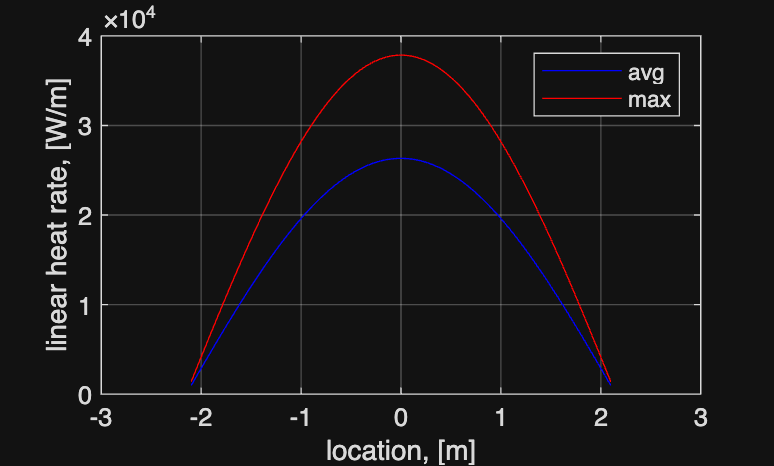

figure(1); grid on; box on; hold on;

xlabel('location, [m]')
ylabel('linear heat rate, [W/m]')
plot(z, q_prim, '-b')
plot(z, q_prim_max, '-r')
legend('avg','max')

Rozkład temperatury w kanale srednim i gorącym

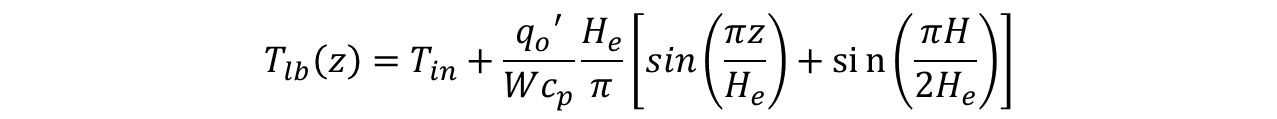

T_lb = Tin + (q0_prim/(W_kanal*cp))*(He/pi)*(sin(pi * z / He) + sin(pi * H / (2 * He)));
T_lb_max = Tin + (q0_prim_max/(W_kanal*cp))*(He/pi)*(sin(pi * z / He) + sin(pi * H / (2 * He)));

Wykres

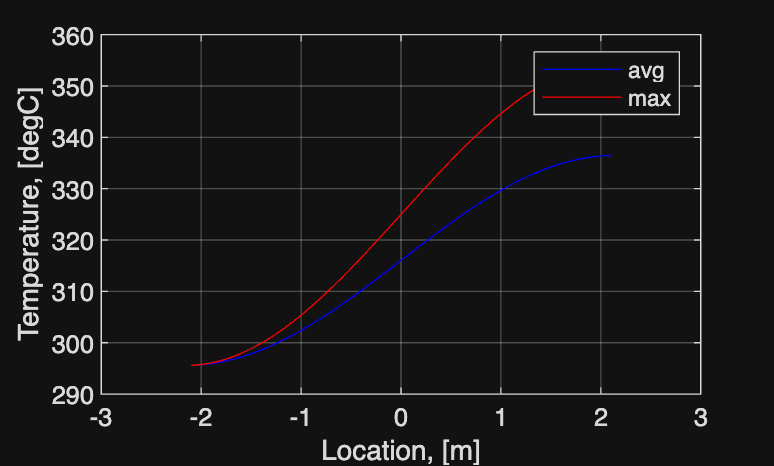

figure(2); grid on; box; hold on;
plot(z, T_lb, '-b')
plot(z, T_lb_max, '-r')
legend('avg','max')
xlabel('Location, [m]')
ylabel('Temperature, [degC]')

# Zadanie 2.2 

## 1) Wyznacz rozkłady temperatury i strumienia ciepła na powierzchni najgorętszego i średniego pręta paliwowego

Zaczynamy od określenia wymiany ciepła między przypływem, a koszulką elementu paliwowego

Dane:

d = 9.5/1000 % średnica pręta paliwowego

d = 0.0095

pitch = 112.6/1000 % skok siatki prętów paliwowych

pitch = 0.1126

Średnica hydrauliczna:

Asqr = pitch^2 - (pi/4)*d^2 % pole przepływu

Asqr = 0.0126

Pw = pi*d % obwód mokry

Pw = 0.0298

Dh = 4*Asqr/Pw % średnica hydrauliczna

Dh = 1.6898

Liczba Reynoldsa oraz Prandtla

G = W_kanal/Asqr % strumień masy

G = 26.0952

mu = XSteam('my_pT', p, Tin) % lepkość dynamiczna

mu = 9.0230e-05

Re = G*Dh/mu % liczba Reynoldsa

Re = 4.8869e+05

cp = 1000*XSteam('Cp_pT', p, Tin)

cp = 5.3566e+03

k = XSteam('tc_pt', p, Tin)

k = 0.5676

Pr = cp * mu / k % liczba Prandtla

Pr = 0.8516

Liczba Nusselta - korelacja Dittusa-Boltera 

Nu_DB = 0.023*(Re^(0.8))*Pr^(0.4) % liczba Nusselta - DB

Nu_DB = 767.4383

Liczba Nusselta - korelacja Markoczego

B = (4/pi)*(pitch/d)^2 - 1

B = 177.8709

Nu_Markoczy = (1 + 0.91*(Re^(-0.1))*(Pr^0.4)*(1 - 2*exp(-B)))*Nu_DB

Nu_Markoczy = 944.1507

Współczynnik przejmowania ciepła

h_DB = Nu_DB*k/Dh

h_DB = 257.7781

h_Markoczy = Nu_Markoczy*k/Dh

h_Markoczy = 317.1348

h = h_Markoczy

h = 317.1348

Przyrost temperatury między przepływem, a powierzchnią paliwa dla średniego i gorącego kanału

deltaT_wall = q_prim./(pi*d*h)

deltaT_wall = 1.0e+03 *

    0.1016    0.1877    0.2736    0.3593    0.4446    0.5295    0.6139    0.6976    0.7808    0.8631    0.9447    1.0253    1.1049    1.1835    1.2610    1.3372    1.4122    1.4858    1.5579    1.6286    1.6977    1.7652    1.8310    1.8950    1.9572    2.0175    2.0759    2.1323    2.1866    2.2388    2.2889    2.3368    2.3825    2.4258    2.4669    2.5055    2.5418    2.5756    2.6069    2.6357    2.6620    2.6858    2.7069    2.7255    2.7414    2.7547    2.7654    2.7734    2.7787    2.7814


deltaT_wall_max = q_prim_max/(pi*d*h)

deltaT_wall_max = 1.0e+03 *

    0.1461    0.2699    0.3935    0.5166    0.6393    0.7614    0.8827    1.0032    1.1227    1.2412    1.3584    1.4744    1.5889    1.7019    1.8133    1.9229    2.0307    2.1365    2.2403    2.3419    2.4413    2.5383    2.6329    2.7250    2.8144    2.9012    2.9851    3.0662    3.1443    3.2195    3.2915    3.3604    3.4260    3.4883    3.5473    3.6029    3.6551    3.7037    3.7487    3.7902    3.8280    3.8621    3.8926    3.9193    3.9422    3.9613    3.9766    3.9882    3.9958    3.9997


Temperatura powierchni koszulki elementu paliwowego

T_co = T_lb + deltaT_wall

T_co = 1.0e+03 *

    0.3972    0.4833    0.5693    0.6550    0.7404    0.8254    0.9099    0.9939    1.0772    1.1597    1.2415    1.3223    1.4022    1.4811    1.5588    1.6353    1.7106    1.7845    1.8570    1.9280    1.9975    2.0654    2.1316    2.1960    2.2587    2.3195    2.3783    2.4352    2.4900    2.5427    2.5933    2.6418    2.6880    2.7319    2.7734    2.8127    2.8495    2.8839    2.9158    2.9452    2.9721    2.9965    3.0183    3.0374    3.0540    3.0679    3.0792    3.0879    3.0938    3.0971


T_co_max = T_lb + deltaT_wall_max

T_co_max = 1.0e+03 *

    0.4417    0.5655    0.6891    0.8124    0.9352    1.0573    1.1788    1.2994    1.4191    1.5378    1.6552    1.7714    1.8862    1.9994    2.1111    2.2210    2.3291    2.4353    2.5394    2.6414    2.7411    2.8385    2.9336    3.0260    3.1159    3.2031    3.2875    3.3691    3.4477    3.5234    3.5959    3.6653    3.7315    3.7944    3.8539    3.9101    3.9628    4.0120    4.0576    4.0997    4.1381    4.1728    4.2039    4.2312    4.2547    4.2745    4.2905    4.3026    4.3109    4.3154


Wykresy

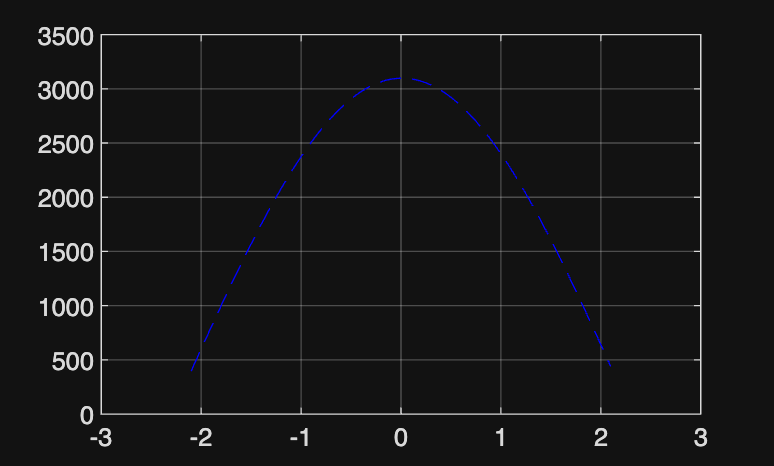

figure(3); grid on; box; hold on; % nowy wykres
%figure(2) % nałóż na wykres temperatury przepływu
hold on;
plot(z, T_co, '--b')

plot(z, T_co_max, '--r')
legend('flow avg','flow max','clad avg','clad max')
%legend('clad avg','clad max')
xlabel('location, [m]')
ylabel('temperature, [degC]')

legend(["flow avg", "flow max", "clad avg", "clad max"], "Position", [0.13 0.74 0.1780, 0.1823])

Obliczenia strumieni ciepła

q_bis =  q0_prim * cos(pi*z/He)/(pi*d)                  % Rozkład mocy liniowej w kanale średnim
q_bis_max =  q0_prim_max * cos(pi*z/He)/(pi*d)          % Rozkłąd mocy liniowej w kanale gorącym

Wykres

figure(4); grid on; box; hold on;
plot(z, q_bis, '-b')
plot(z, q_bis_max, '-r')
legend('avg','max')
xlabel('location, [m]')
ylabel('heat flux, [W/m2]')

## 2) Oszacuj lokalizację i maksymalną temperaturę i strumień ciepła na zewnętrznej powierzchni koszulki najgorętszego pręta paliwowego

Określ maksymalną temperaturę

max(T_co)
[~, indeks1] = max(T_co)
z(indeks1)
max(T_co_max)
[~, indeks2] = max(T_co_max)
z(indeks2)

Określ lokalizację maksymalnej temperatury

Określ maksymalny strumień ciepła wraz z lokalizacją

max(q_bis)
[~, indeks1] = max(q_bis)
z(indeks1)
max(q_bis_max)
[~, indeks2] = max(q_bis_max)
z(indeks2)

Określ lokalizację